# 034IN - Fundamentals of Automatic Control - A.Y. 2024/2025

# First Partial Examination - 2025/04/11

# Exercise 2C: From an ODE Set to State Equations, then to a Transfer Function

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC] `

## Introduction

Consider a system consisting of a electric motor driving two masses that are connected by a torsional spring, as shown in Figure

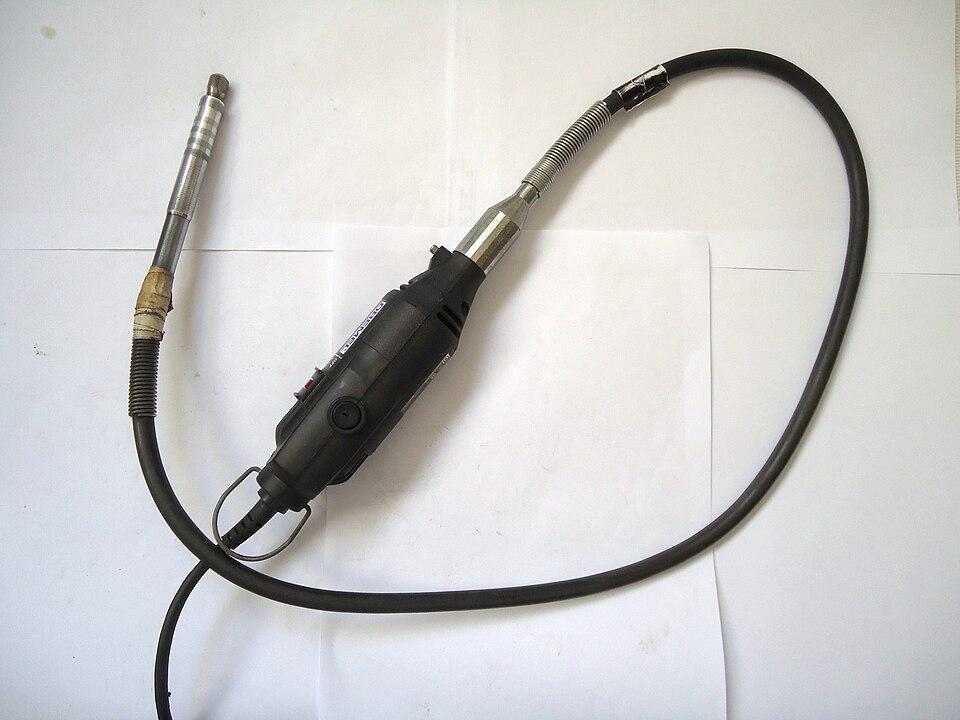   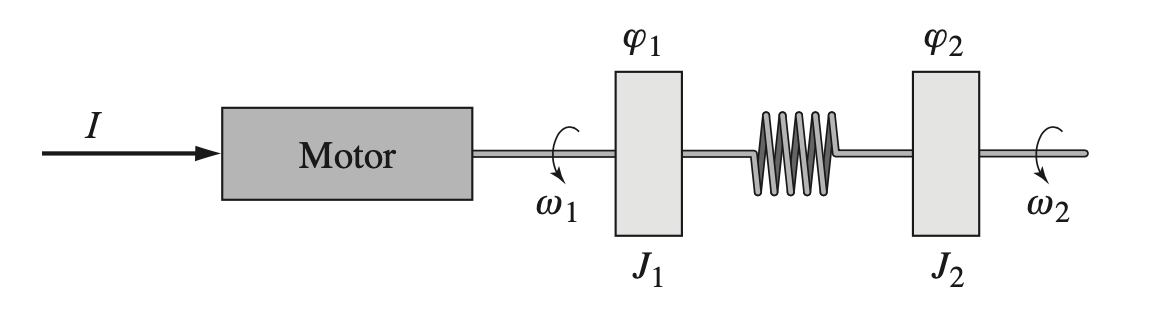

             Figure (a): source [1]                                               Figure (b)                                      

This system can represent a motor with a flexible shaft that drives a load (as in Figure (a) ). Assuming that the electric drive delivers a torque that is proportional to the current $I$, the dynamics of the system can be described by the following set of** two second-order linear ODEs** 


$$\left\{\begin{array}{rcl}
J_1 \ddot{\varphi}_1(t) + c\big(\dot{\varphi}_1(t)-\dot{\varphi}_2(t) \big) + k \big(\varphi_1(t) - \varphi_2(t) \big) &=& k_I\, u(t)\ \\
J_2 \ddot{\varphi}_2(t) - c\big(\dot{\varphi}_1(t)-\dot{\varphi}_2(t) \big) - k \big(\varphi_1(t) - \varphi_2(t) \big) &=& 0\\ \\
y(t) &=& \dot{\varphi}_2(t)

\end{array}\right. \qquad \quad(*)$$


where

- $\varphi_1$ and $\varphi_2$ are the angles of the two masses;

- $\omega_i :=\dot{\varphi}_i\,,\; i=1,\,2$ are their velocities;

- $J_i,\;i=1,\,2$ represent moments of inertia;

- $c$ is the damping coeﬃcient;

- $k$ represents the shaft stiffnes;

- $k_I$ is the torque constant for the electric drive

Similar equations are obtained for a robot with flexible arms and for the arms of DVD and optical disk drives.

You are asked to 

- determine a **state-space representation** $\mathcal{S}$ of the balance system described by the ODEs $(*)$, assuming the following state variables


$$\left\{\begin{array}{rcl}
x_1(t) &:=& \varphi_1(t) \\
x_2(t) &:=& \dot{\varphi}_1(t) = \dot{x}_1(t) \\
x_3(t) &:=& \varphi_2(t) \\
x_4(t) &:=& \dot{\varphi}_2(t) = \dot{x}_3(t)
\end{array} \right. \qquad (+)$$


- given the state-space representation $\mathcal{S}$, compute the corresponding **transfer** **function** $T_{u\,y}(s)$ from the input $u(t)$ to the output $y(t)$;

- use the transfer function $T_{u\,y}(s)$ to determine the **realisation** **in** **Control** **Form** of the system. Refer to **Part 4** of the course material for details.

## Assignment

**Note**: the parameters $J_1$, $J_2$, $k$, $k_I$, $c$ have been predefined and they are available as the numeric variables   `J1, J2, k, kI_p, c` in the initial part of your code.

### Task 1

Your code shall

- define the numeric matrices `matA`, `matB`, `matC`, `matD` of the state equations describing the sistem $(*)$ by means of the state variables defined in $(+)$; 

- assign to the variable `SysSS1` the state-space description obtained by applying the MATLAB command `ss`;

- determine the representation as transfer function of `SysSS1`, using the MATLAB command `tf`. Assign the result to the variable `SysTF`. 

## Solution

load FlexibleShaftElDrive.mat
whos

  Name      Size            Bytes  Class     Attributes

  J1        1x1                 8  double              
  J2        1x1                 8  double              
  c         1x1                 8  double              
  k         1x1                 8  double              
  kI_p      1x1                 8  double              



### Task 1

Let's rewrite the ODEs according to Eq. $(+)$, with the aim to obtain the required state-space representation:


$$\left\{\begin{array}{rcl}
\dot{x}_1(t) &=& x_2(t) \\ \\
\dot{x}_2(t) &=& -\frac{k}{J_1}\, x_1(t) - \frac{c}{J_1} x_2(t)   +\frac{k}{J_1}\, x_3(t) +\frac{c}{J_1} x_4(t)+ \frac{k_I}{J_1}\,u(t) \\ \\
\dot{x}_3(t) &=& x_4(t) \\ \\
\dot{x}_4(t) &=&  +\frac{k}{J_2}\, x_1(t) + \frac{c}{J_2} x_2(t)   -\frac{k}{J_2}\, x_3(t) -\frac{c}{J_2} x_4(t)\\ \\
y(t) &=& x_1(t)

\end{array}\right. \qquad \quad(**)$$


Now, assign the matrices corresponding to Eq. $(**)$ in MATLAB:

% ---- the matrices corresponding to Eq. (**) ----
matA = [  0  ,    1  ,    0  ,    0  ;
        -k/J1,  -c/J1,  +k/J1,  +c/J1;
          0  ,    0  ,    0  ,    1  ;
         k/J2,  c/J2 ,  -k/J2,  -c/J2 ];

matB = [    0  ;
        kI_p/J1;
            0  ;
            0  ];

matC = [0,  0,  0,  1];

matD = 0;



% --- the LTI system as ss object ---
SysSS1 = ss(matA, matB, matC, matD)


SysSS1 =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2    -0.0002  -0.000325     0.0002   0.000325
   x3          0          0          0          1
   x4      0.001   0.001625     -0.001  -0.001625
 
  B = 
         u1
   x1     0
   x2  0.55
   x3     0
   x4     0
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% ---- finally, the LTI system described by using a tf object ----
SysTF = tf(SysSS1)


SysTF =
 
           0.0008938 s^2 + 0.00055 s + 2.316e-22
  --------------------------------------------------------
  s^4 + 0.00195 s^3 + 0.0012 s^2 - 2.658e-22 s - 2.464e-24
 
Continuous-time transfer function.
Model Properties


## References

[1] [https://en.wikipedia.org/wiki/Flexible_shaft#/media/File:Flexible_shaft_motor.jpg](https://en.wikipedia.org/wiki/Flexible_shaft#/media/File:Flexible_shaft_motor.jpg) 